Generic starter code to close open figures and clear memory before starting.

clc;
close all;
clear;

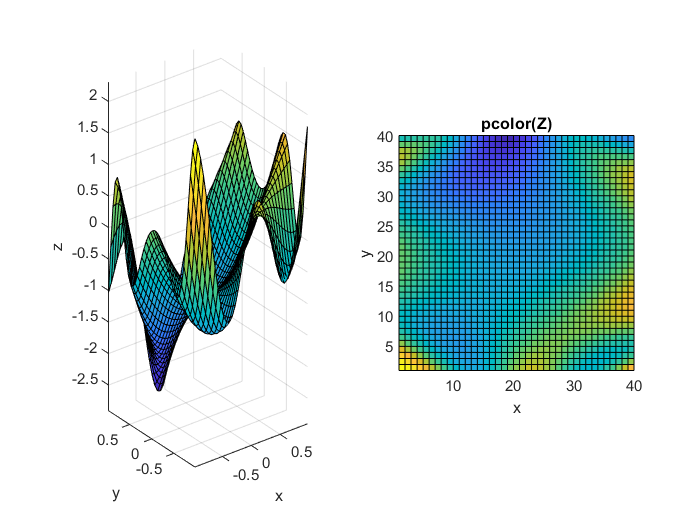

close
% This generates: -0.975 -0.925 .... 0.925 0.975, 40 points equally spaces
% in [-1,1] separated by a distance of 2/40 = 0.05
x = linspace(-0.975,0.975,40);
y = x;
% This makes the x,y - plane as far as MATLAB is concerned. 
% X is a 40 x 40 matrix and (X(i,j), Y(i,j)) is what you 
% would use as (x_i, y_j)
[X,Y] = meshgrid(x,y);    
% Define the surface
Z = sin(2*pi*X.*Y.^2 - Y) - cos(4*pi*X.^2*Y + X) + X.^2 - Y.^3;
% Actually plot the surface

figure(1);
subplot(1,2,1);
surf(X,Y,Z);
xlabel('x');
ylabel('y');
zlabel('z');
axis([-1 1 -1 1 -3 2.5], 'equal');

subplot(1,2,2);
pcolor(Z);
title('pcolor(Z)');
xlabel('x');
ylabel('y');
axis('square');

% Choose what rank approximation to investigate

N = 1;

% This tiny bit of code does all the work
[U,S,V] = svd(Z);
% Here is the rank N approximation
ZZ = U(:,1:N)*S(1:N,1:N)*V(:,1:N)';


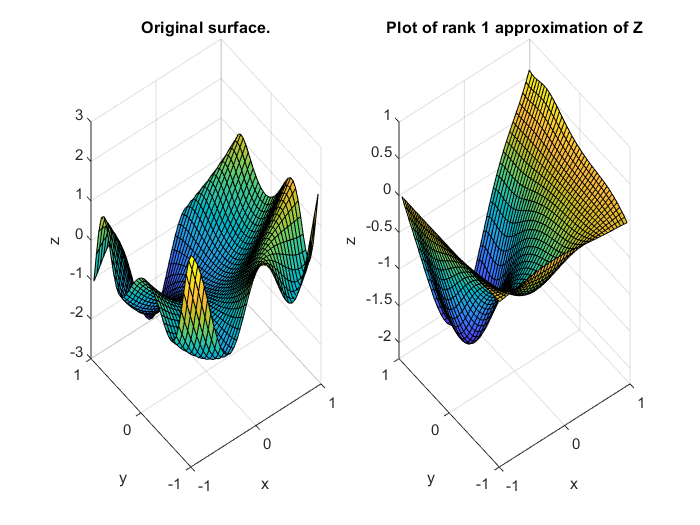

close
% Build a title that depends on N
str = ['Plot of rank ', num2str(N), ' approximation of Z'];

% This plots the actual surfaces Z and Z(N)
f3 = figure(3);
subplot(1,2,1);
surf(X,Y,Z);
xlabel('x');
ylabel('y');
zlabel('z');
title("Original surface.")


subplot(1,2,2);
surf(X,Y,ZZ);
xlabel('x');
ylabel('y');
zlabel('z');
title(str);

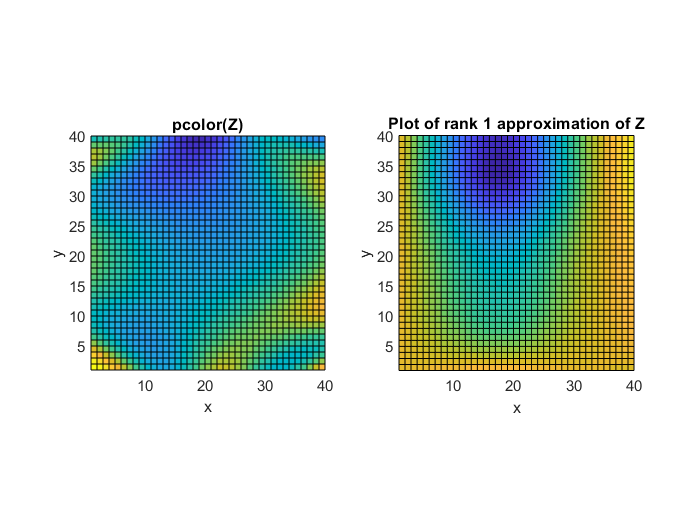



% This shows the matrices with values color-coded.
f4 = figure(4);

subplot(1,2,1);
pcolor(Z);
title('pcolor(Z)');
xlabel('x');
ylabel('y');
axis('square');

subplot(1,2,2);
pcolor(ZZ);
title(str);
xlabel('x');
ylabel('y');
axis('square');

This plots the first N singular values.

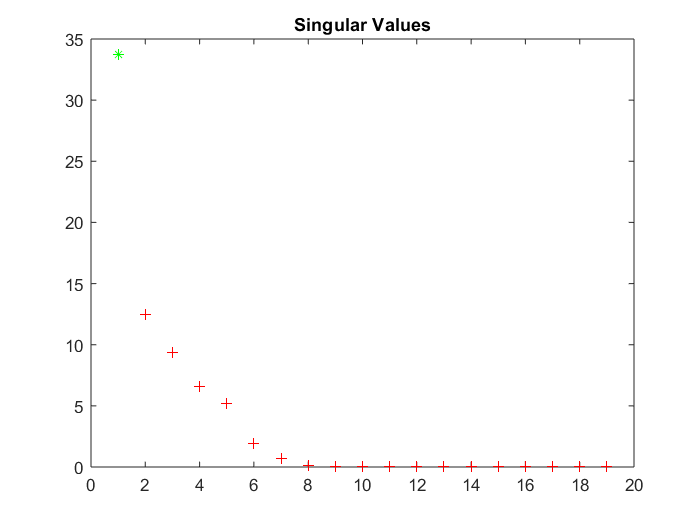

close
f5 = figure(5);
D = diag(S);
A = D(1:rank(S));
B = D(1:N);
plot(A,'r+');
hold on;
plot(B,'g*');
title("Singular Values")

This part plots the sequence of $u_i$'s and $v_i$'s

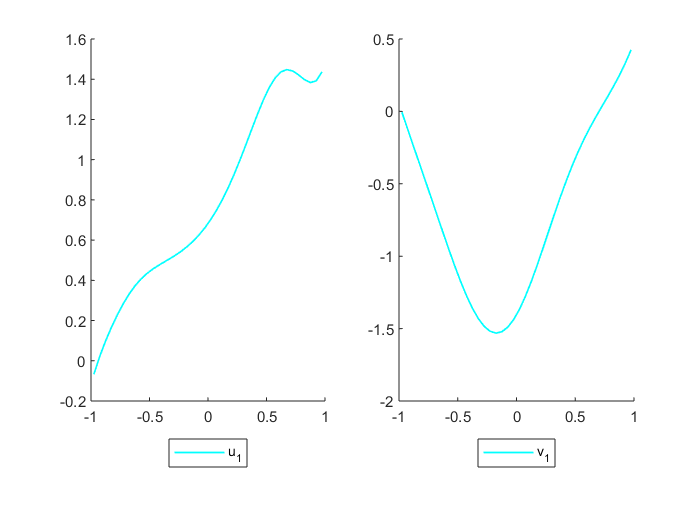

close
f6 = figure(6);

% Have to do some non-sense to get the right coloring/labels 
lgu = [];
lgv = [];
for i = 1:N
    
    su = ['"', 'u_', num2str(i), '"'];
    sv = ['"', 'v_', num2str(i),'"'];
    [lgu_1,lgu_2] = size(lgu);
    if (lgu_2) == 0
        lgu = [su];
        lgv = [sv];
    else
        lgu = [lgu, ',', su];
        lgv = [lgv, ',', sv];
    end
    
    subplot(1,2,1);
    hold on;
    plot(Y(:,1), sqrt(B(i))*U(:,i), 'color', [0, i/N, 1 - (i-1)/N], 'linewidth', 1.0);
    
    subplot(1,2,2);
    hold on;
    plot(X(1,:), sqrt(B(i))*V(:,i)', 'color', [0,  i/N, 1 - (i-1)/N],'linewidth',1.0);
end

subplot(1,2,1);
eval(['legend(', lgu, ', "location", "southoutside")']);
legend('boxon');
hold off;

subplot(1,2,2);
eval(['legend(', lgv, ', "location", "southoutside")']);
legend('boxon');
hold off;

variance_accounted_for = sum(diag(S(1:N,1:N)).^2)/sum(diag(S(1:rank(Z),1:rank(Z))).^2);

error = sum(sum((ZZ - Z).^2));

dA = (X(1,2)-X(1,1))*(Y(2,1)-Y(1,1));

disp(['variance accounted for = ', num2str(round(variance_accounted_for*100,2)),'%'])
fprintf("L^2 error = %.2f", error)
disp(['Squared area between surfaces = ', num2str(error*dA)])

variance accounted for = 97.85%


L^2 error = 31.31

Squared area between surfaces = 0.078281
